# Übung: Segmentierung von Puzzleteilen

Feature Detection und Matching sind mächtige Werkzeuge, was aber, wenn wir eingrenzen möchten wo im Bild überhaupt nach Features gesucht werden soll? Wenn wir beispielsweise einen störenden Hintergrund ignorieren, oder Fachwissen über die erwarteten Bilder nutzen möchten, benötigen wir einen Vorverarbeitungsschritt.

In dieser Übung werden wir einen Vorverarbeitungsschritt implementieren, der Puzzleteile in einem Bild findet, vom Hintergrund separiert und labelt. In diesem Szenario gehen wir von verschiedensten möglichen (Bild-) Hintergründen aus. Was für Möglichkeiten haben wir eine solche Segmentierungsaufgabe anzugehen?

## Segmentierung

Die moderne Bildverarbeitung hat dafür (quasi Objekterkennung auf abweichenden Hintergründen) normalerweise eine klare Antwort: Deep Learning. Da uns allerdings die dafür nötige Datenmenge fehlt, werden wir eine Alternative finden müssen.

Wir werden unser Verfahren auf der Kantenerkennung aufbauen, somit benötigen wir keine festgelegten Farben (Green Screen) und sind weniger anfällig für Beleuchtungsunterschiede im Bild. Im speziellen verwenden wir den bekannten Canny-Algorithmus, dieser ist besonders robust gegenüber Rauschen und liefert auch bei "schwächeren" Kanten gute Ergebnisse. Anschließend werden wir das erzeugte Kantenbild mit verschiedenen Verfahren in eine Maske umwandeln, die Puzzleteile im Bild klar vom Hintergrund trennt.

# Praxis

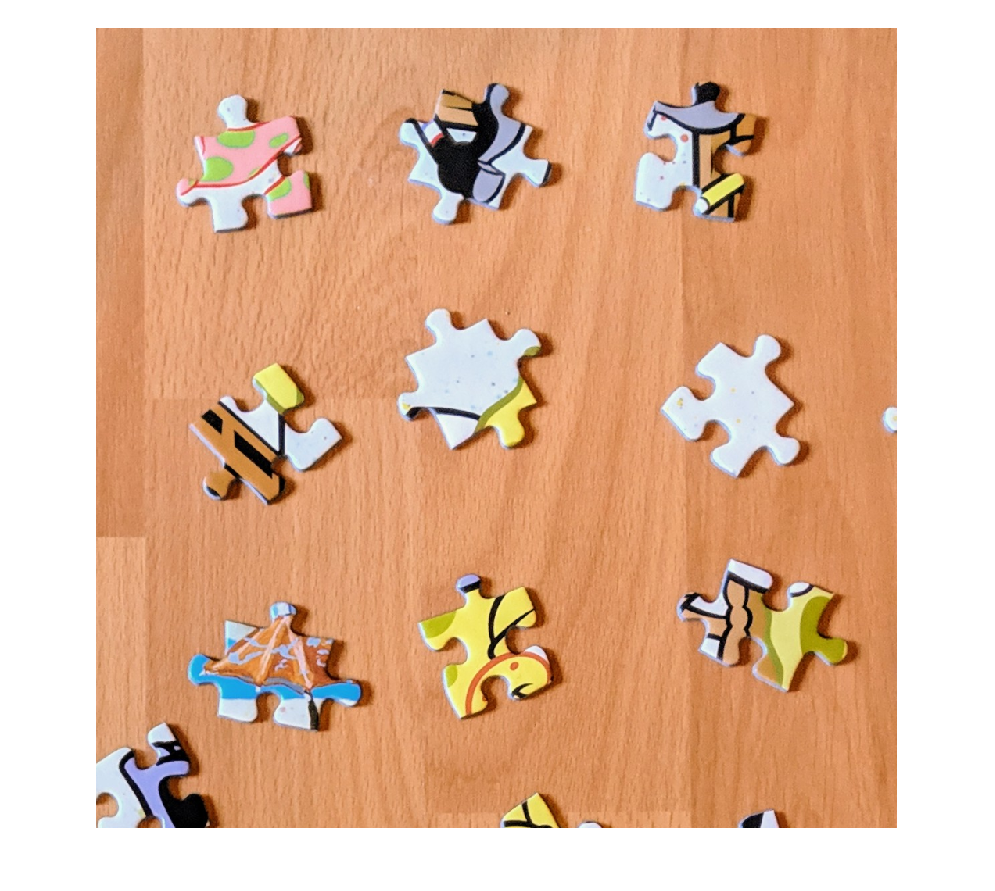

% Lädt für die Übung benötigte Dateien
piecesRGB = im2double(imread("images/puzzle/spongebob_pieces_bright.jpg"));
piecesRGB = imcrop(piecesRGB, [2000,0,1200,1200]);
imshow(piecesRGB)

## Schritt 1: Kantenbild erzeugen

Das Ausgangsbild ist in der Variable `piecesRGB` gespeichert. Die Funktion für Kantenbilder heißt `edge`, sie erwartet:

- ein *Grauwertbild (suche in der Dokumentation nach *`rgb2gray`*).*

- die zu verwendende Methode, in unserem Fall `'Canny' für den Canny-Algorithmus.`

- `den Schwellwert*. Experimentiere mit diesem Parameter um alle Außenkanten der Puzzleteile zu erkennen und dabei möglichst wenig Kanten im Hintergrund zu haben.`

Lege eine Variable `mask` an, die das erzeugte Kantenbild enthält.

mask = edge(rgb2gray(piecesRGB), 'Canny', 0.14);

** Anmerkung*: der Canny-Algorithmus arbeitet intern mit 2 Schwellwerten, siehe [Dokumentation](https://www.mathworks.com/help/images/ref/edge.html).

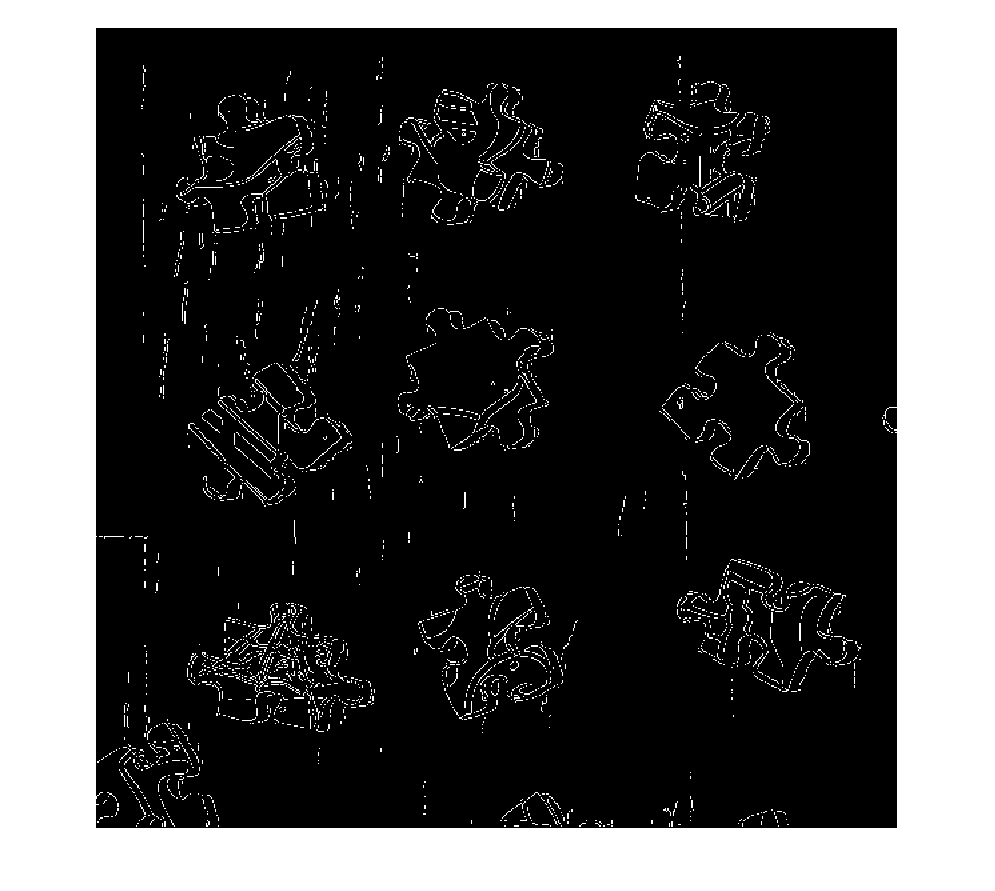

imshow(mask, [])

## Schritt 2: Lücken im Kantenbild schließen

Öffne das Kantenbild und vergrößere eines der Puzzleteile. Wie du siehst, sind die "Kantenpixel" gut erkannt worden, es finden sich dennoch viele Lücken. Wir werden Gauß Glättung verwenden und das Bild so stark verwaschen, das diese zu schließen. Dies ist ein naiver Ansatz, der aber für unsere Zwecke ausreichende Ergebnisse liefert. Der Vollständigkeit halber verlinke ich hier aber noch eine fortgeschrittenere [Alternative](https://www.peterkovesi.com/matlabfns/#edgelink).

Glätte das Kantenbild mit dem Gauß Filter. Die Funktion dafür heißt `imgaussfilt, sie erwartet ein Eingabebild vom Typ double`  und die Filtergröße. Experimentiere mit der Filtergröße mit dem Ziel unterbrochene Kanten zu verbinden (führe dafür diesen Abschnitt aus und betrachte das Ergebnis). Überschreibe die `mask` Variable mit dem Ergebnis.

mask = imgaussfilt(double(mask), 2);

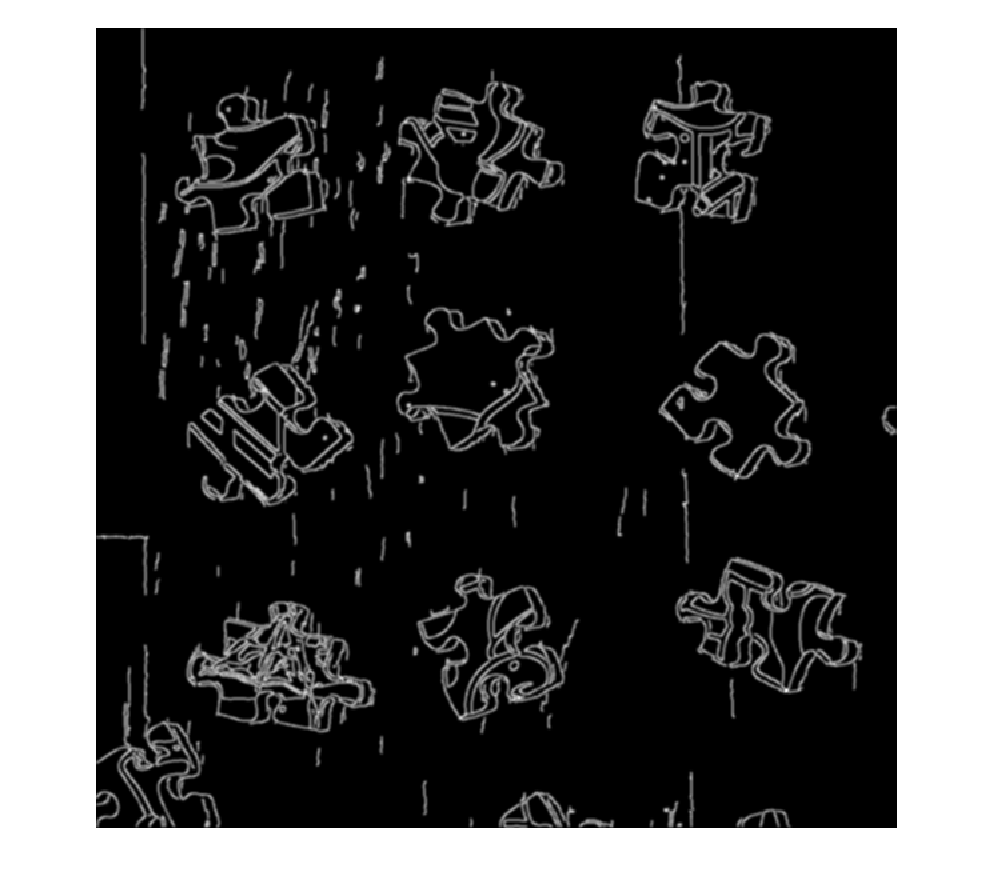

imshow(mask, [])

## Schritt 3: Umwandeln in eine Maske

Jetzt werden wir das Kantenbild mit durchgängigen Kanten in eine Maske verwandeln. Dazu werden wir schlicht einen Flood Fill Algorithmus einsetzen, um den Hintergrund bis zu den erkannten Kanten der Puzzleteile zu füllen (deshalb sind durchgängige Kanten auch so wichtig).

Der Flood Fill Algorithmus erwartet ein Binärbild, daher muss die bisherige Maske erst binärisiert werden. Nutze dafür die `imbinarize` Methode, diese erwartet:

- ein Eingabebild (die Maske)

- die Schwellwert Methode. Wir werden `"adaptive"` verwenden um möglichst viele Kanten zu erhalten (im Gegensatz zu einem *globalen* Schwellwert für das gesamte Bild).

- einen zusätzlichen Parameter `"Sensitivity" (Range [0 ; 1 ]). Welchen Wert müssen wir wählen um möglichst viele Kanten zu erhalten? Zieh dazu die Dokumentation zurate.`

Überschreibe die `mask` Variable mit dem Ergebnis. Gib das Ergebnis anschließend mit `imshow` aus.

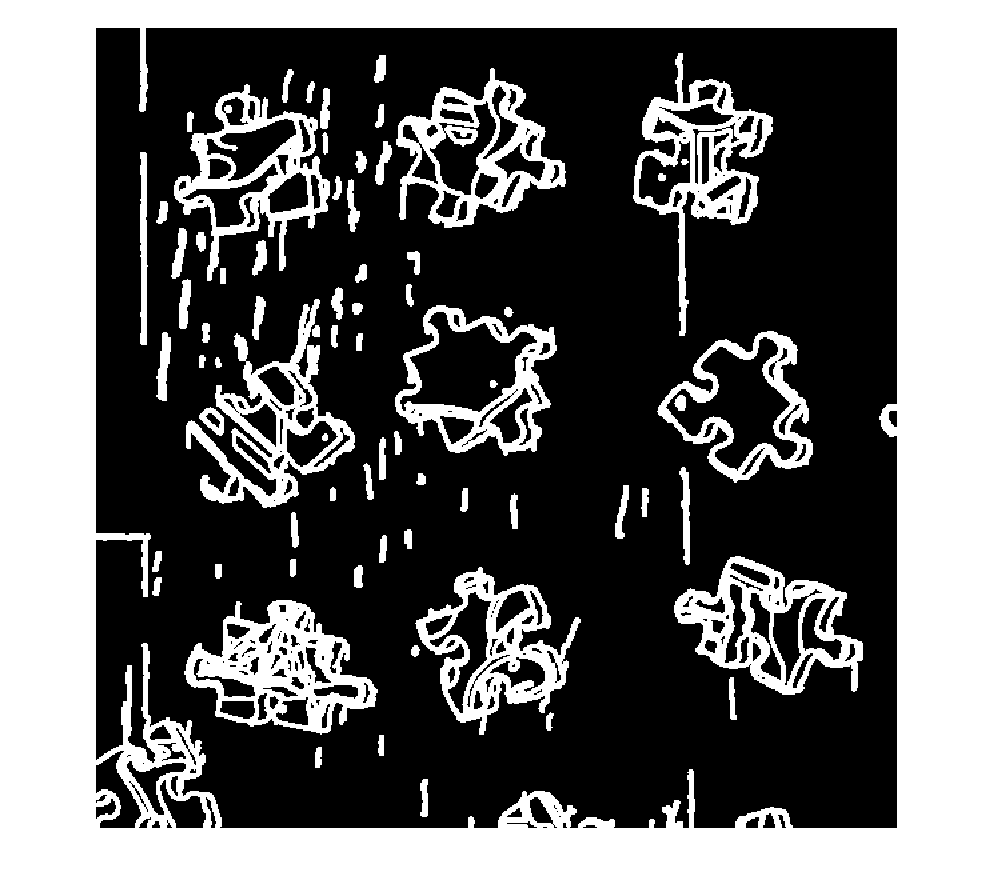

mask = imbinarize(mask, "adaptive", "Sensitivity", 1.0);
imshow(mask, [])

Wende jetzt den Flood Fill Algorithmus mit `imfill` an. Übergib unsere Maske als Eingabebild, als Startkoordinate kannsts du [1 1] angeben, der Algorithmus füllt dann von dort ausgehend schwarze Flächen bis er auf weiße Pixel trifft.

Schreibe das Ergebnis in eine neue Variable `fill`` und lass es dir mit imshow anzeigen.`

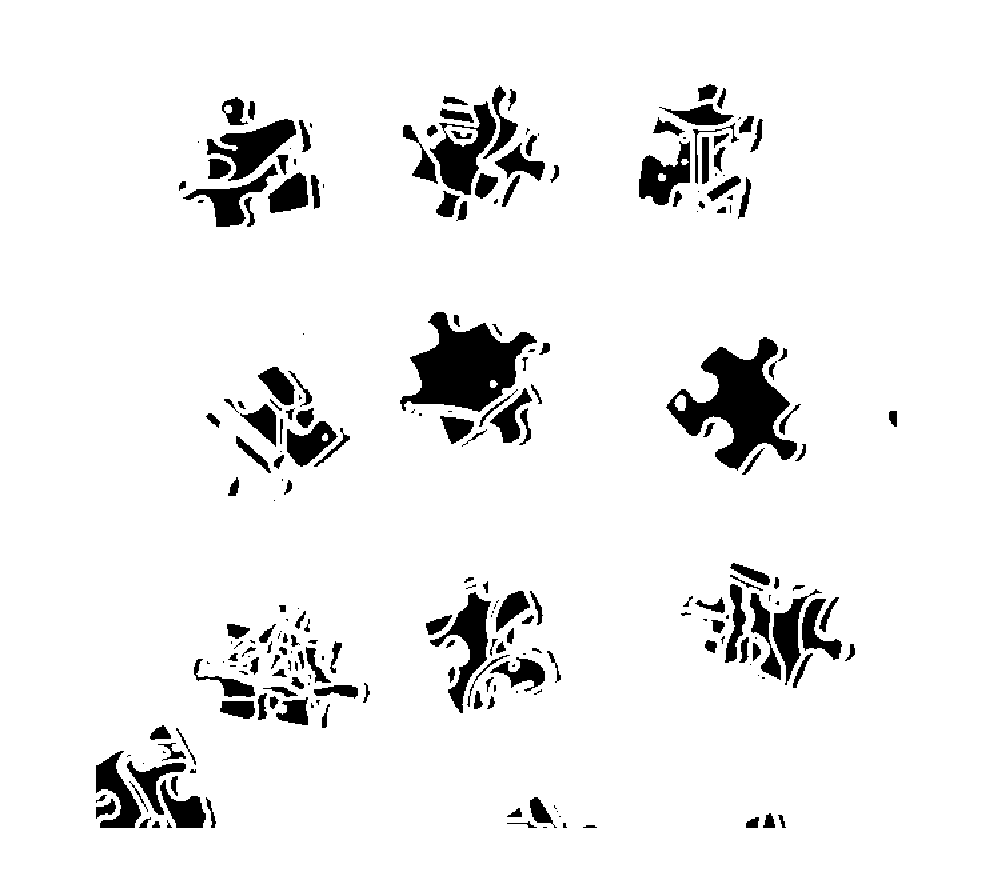

fill = imfill(mask, [1 1]);
imshow(fill, [])

`Was für ein Problem haben wir?`

`imfill füllt das Bild mit logisch 1 (weiß) und überschreibt damit unsere Kanteninformationen (ebenfalls weiß im der Maske). Ziehe unsere bisherige Maske (mask) von der gefüllten Fläche (fill) ab, überschreibe mask mit dem Ergebnis und lass es ebenfalls anzeigen.`

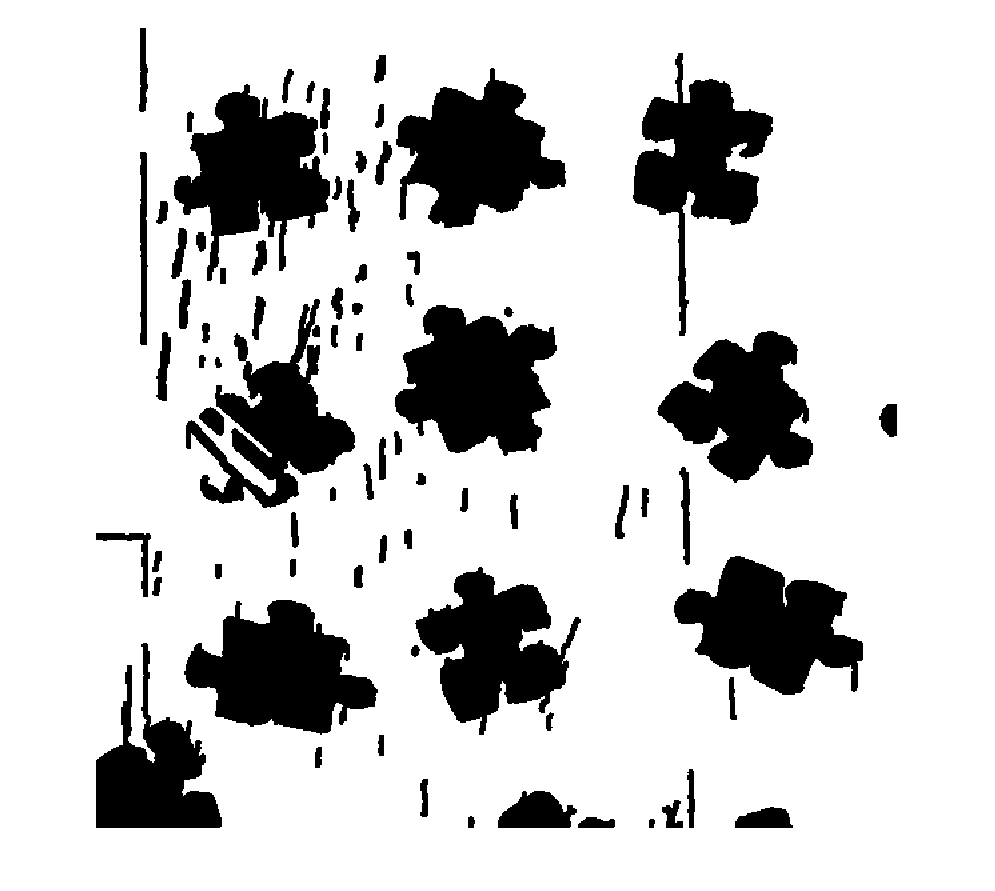

mask = fill - mask;
imshow(mask, [])

Das Problem ist behoben, aber unsere Maske ist "verkehrt herum", der Hintergrund ist mit logisch 1 gefüllt, wir interessieren uns aber für die Puzzleteile statt dem Hintergrund. Daher müssen wir die Maske noch invertieren. Dazu nutzen wir die `imcomplement` Funktion, die nur eine Eingabebild (unsere Maske) erwartet.

Überschreibe die `mask` Variable mit dem Ergebnis.

mask = imcomplement(mask);

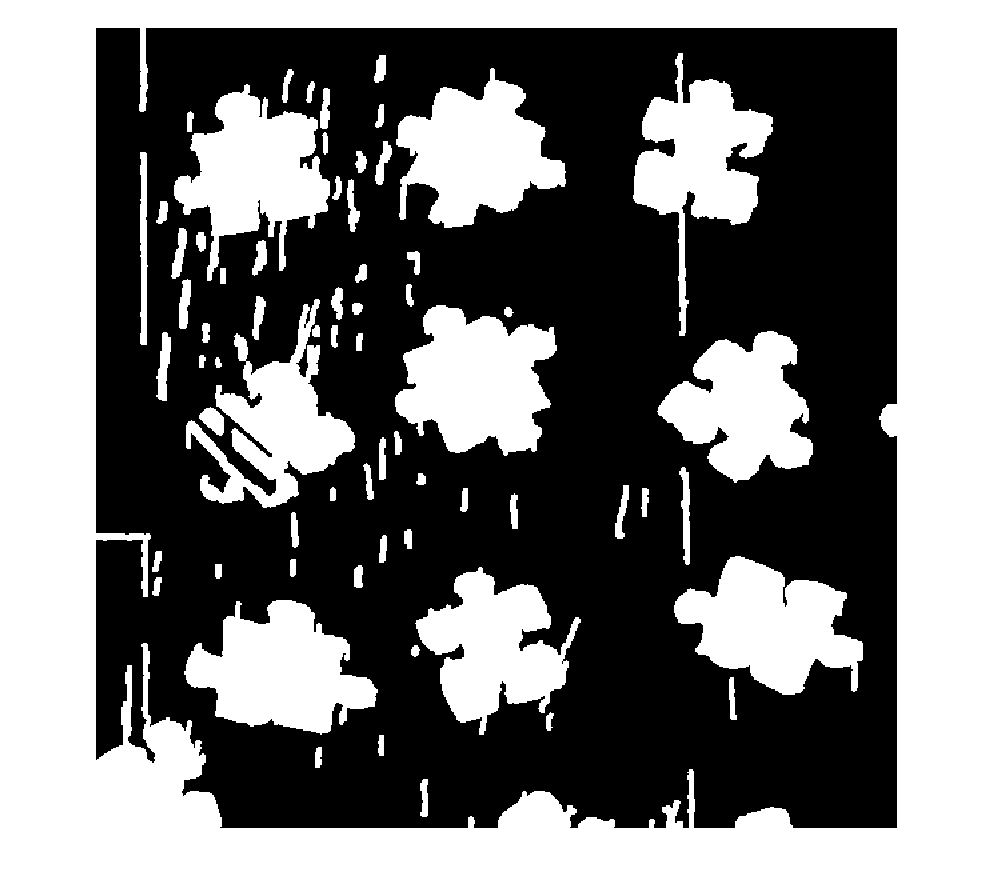

imshow(mask, [])

## Schritt 4: Entfernen von Ausreißern

Wie du dich sicher erinnerst, haben wir den Gauß Filter genutzt um Löcher in den Kanten zu füllen. Diese Operation hat einen unschönen Seiteneffekt, sie "weicht" die Kanten auf. Um dem entgegen zu wirken nutzen wir jetzt die `imerode` Funktion, diese erodiert die Kanten von Objekten, trägt also Pixel ab. Dafür erwartet sie:

- ein Eingabebild (die Maske).

- die Form der Erosion, da Puzzleteile oft ründliche Formen haben wählen wir die Form `"disk". Schaue in der Dokumentation zu imerode nach wie die Formen angegeben werden und experimentiere mit der Größe des Radius.`

Überschreibe die `mask` Variable mit dem Ergebnis.

mask = imerode(mask, strel("disk", 5));

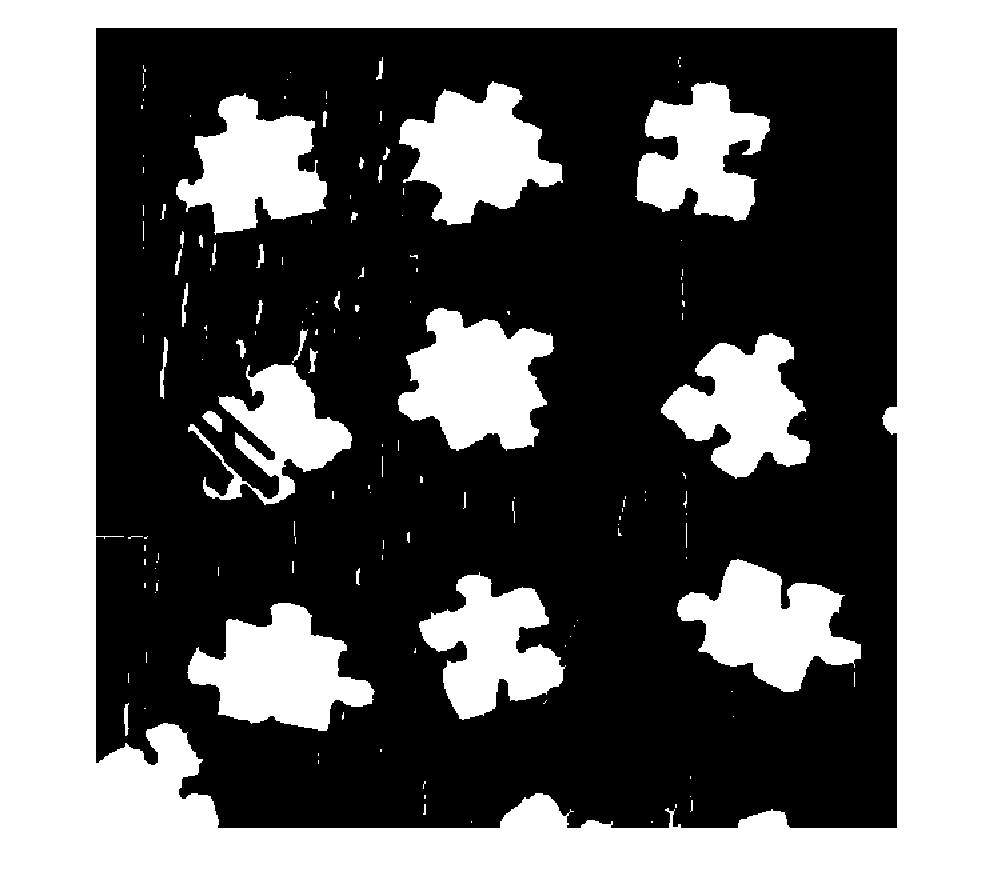

imshow(mask, [])

Jetzt kommt der abschließende Schritt, der unser bisheriges Ergebnis in eine tatsächlich brauchbare Maske verwandelt. Wir werden sehr kleine zusammenhängende Pixelflächen entfernen (einzelne Pixel, dünne alleinstehende Kanten). Das funktioniert in MATLAB sehr einfach mit der `bwareaopen` Funktion. Diese erwartet:

- ein Eingabebild (die Maske).

- die minimale Größe von Pixelflächen (in Pixeln), ab der sie *nicht mehr entfernt* werden. Dieser Wert hängt von der Auflösung des Bildes ab, in diesem Fall kannst du 1000 wählen.

Überschreibe die `mask` Variable mit dem Ergebnis.

mask = bwareaopen(mask, 1000);

Mit nur einer Operation entfernen wir alle verbleibenden Störungen unserer Maske, der Unterschied ist beeindruckend!

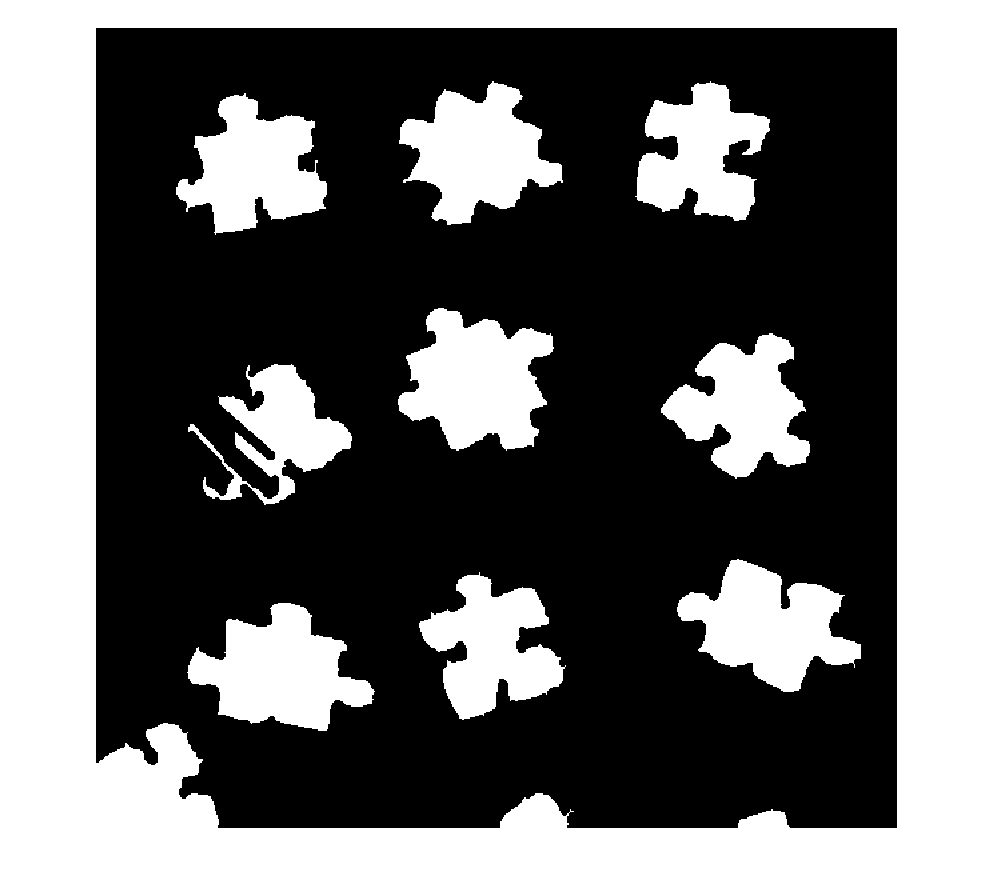

imshow(mask, [])

## Schritt 5: Anwendung der erzeugten Maske visualisieren

In diesem letzten Schritt wenden wir unsere Maske auf das ursprüngliche Bild (`piecesRGB`) an. Verwende dafür die elementweise Multiplikation in MATLAB, und gib das Ergebnis direkt mit `imshow` aus.

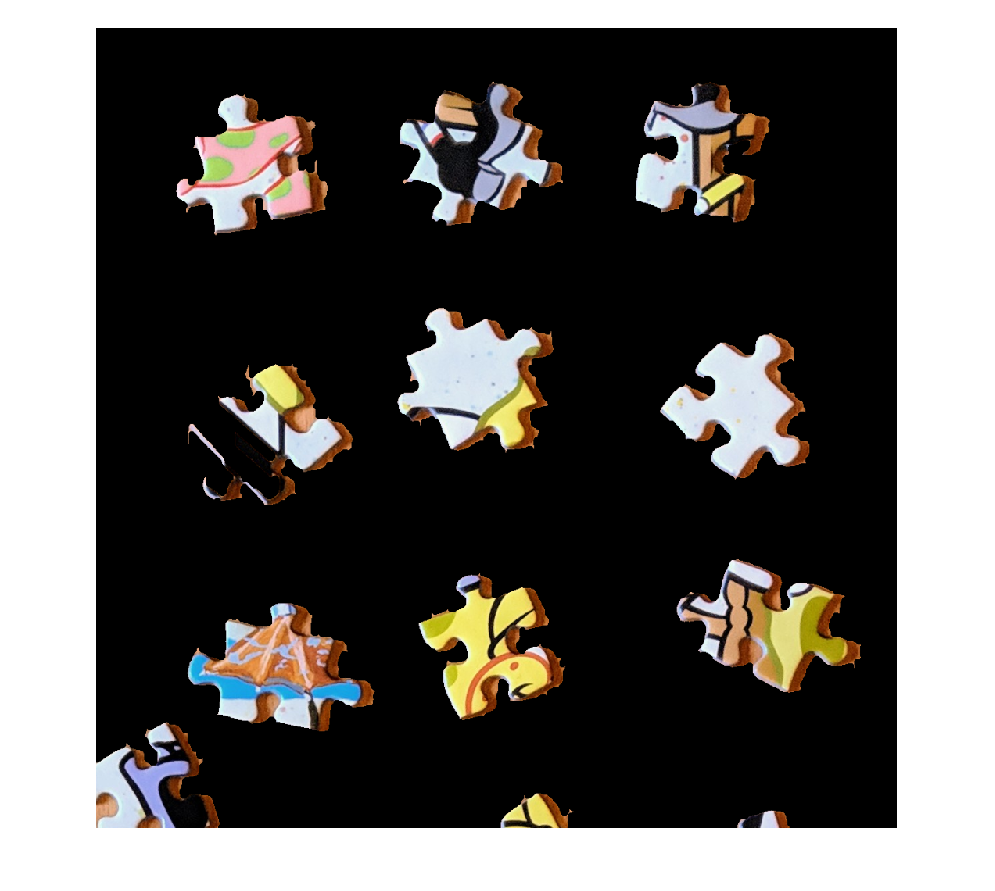

imshow(piecesRGB .* mask, [])

Wie du siehst*, separiert unsere Maske die Puzzleteile relativ sauber vom Hintergrund, trotz seines komplexen Holzmusters. Einzig die Schatten der Puzzleteile im Bild sind erhalten geblieben und bei einem Teil (das mittlere linke) hat die Maskierung versagt. Betrachte nochmal das Ausgangsbild, erkennst du den Grund?

Das betroffene Puzzleteil ist an der Stelle kaum vom Hintergrund zu unterscheiden, die Kante ist selbst für einen Menschen nicht direkt ersichtlich. Eine Möglichkeit solche Probleme zu umgehen wäre der Einsatz eines komplexeren Edge Linking Verfahrens, mit einem (relativ) großen Suchradius. Implementierungen dafür findest du auf dem vorhin bereits aufgeführten Link: [Alternative](https://www.peterkovesi.com/matlabfns/#edgelink).

Damit hast du das Tutorial abgeschlossen, Ich hoffe es hat dir Spaß gemacht. Im nächsten Abschnitt zeige ich als kleinen Bonus noch, wie man in MATLAB über die einzelnen Puzzleteile iterieren kann.

* Falls du passende Parameter gefunden hast, wenn nicht schaue am Ende der Datei.

# Vergleich: Ausgangsbild & maskiertes gelabeltes Ergebnis

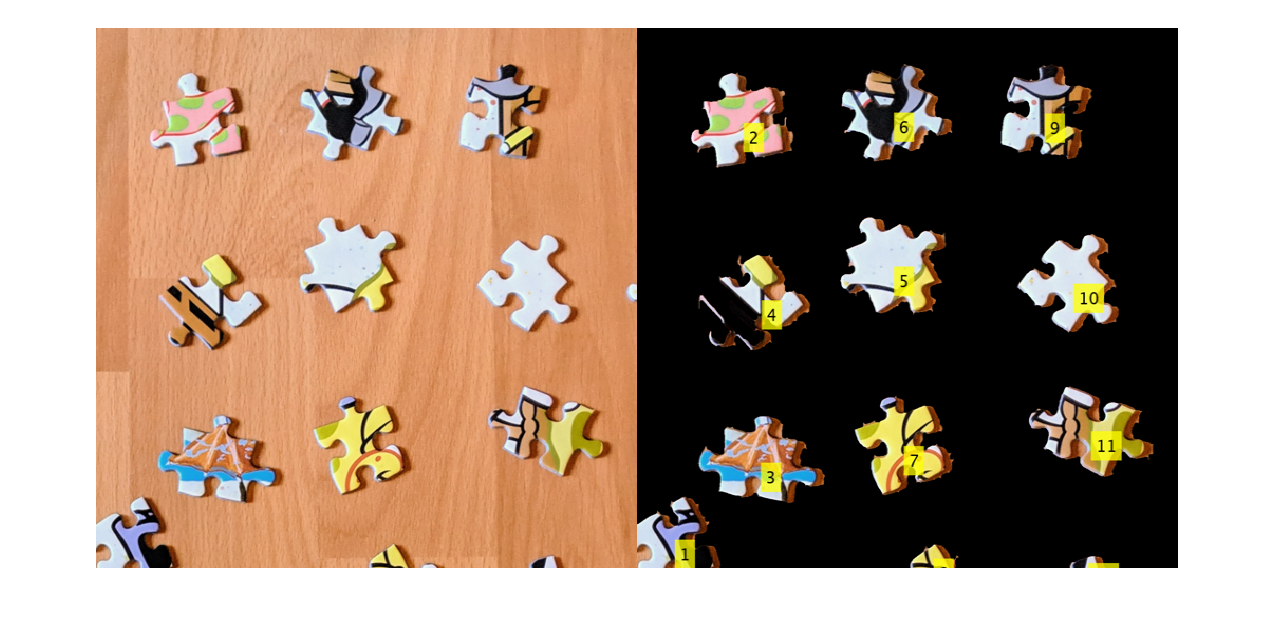

[labeled,labelCount] = bwlabel(mask);

index = 1;
labelOverlayed = piecesRGB .* mask;
while index <= labelCount
    labelOverlayed = insertText(labelOverlayed, ...
        regionprops(labeled==index,'Centroid').Centroid, ...
        index, ...
        "FontSize",36,"BoxOpacity",.75);
    index = index + 1;
end
montage({piecesRGB, labelOverlayed})

# Spoiler: Geeignete Werte für die gezeigten Verfahren

- **Canny**: 0.14

- **Gauß**: 2

- **imbinarize Sensitivity**: 1.0

- **imerode Disk Radius**: 5

- **bwareaopen**: 1000